## **Rozkład Gaussa - przykład rozkładu inteligencji IQ w populacji**

[[wiki] Rozkład normalny](https://pl.wikipedia.org/wiki/Rozk%C5%82ad_normalny)

clear all
close all
clc
clearvars


Informacje o IQ

[[wiki] Test ilorazu inteligencji IQ](https://pl.wikipedia.org/wiki/Iloraz_inteligencji#)

%web("https://pl.wikipedia.org/wiki/Iloraz_inteligencji#/media/Plik:IQ_curve.svg")

Parametry:

mu=100 % wartość oczekiwana (średnia)

mu = 100

sigma=15 %odchylenie standardowe

sigma = 15

Zakres wartości

x=0:0.01:200

x =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


Funkcje:

**makedist** - *Create probability distribution object*

oraz

 **pdf - ***Probability density function*

[Funkcja "makedist"](https://www.mathworks.com/help/releases/R2020a/stats/makedist.html)

[Funkcja "pdf"](https://www.mathworks.com/help/releases/R2020a/stats/prob.normaldistribution.pdf.html)

%web(fullfile(docroot, 'stats/makedist.html'))
%web(fullfile(docroot, 'stats/prob.normaldistribution.pdf.html'))

Wykres rozkładu normalnego


$$f\left(x\right)=\frac{1}{\sigma \sqrt{2\Pi }}e^{-\frac{{\left(x-\mu \right)}^2 }{2\sigma^2 }}$$


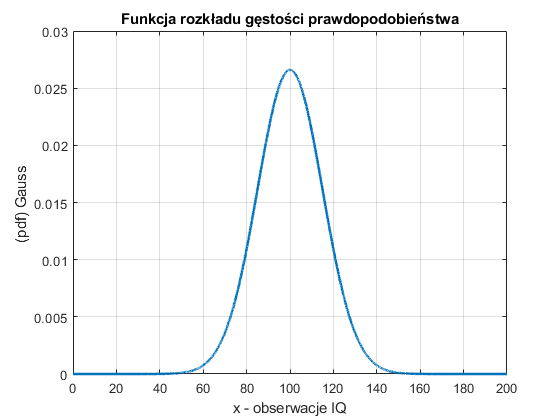

pd=makedist('Normal','mu',mu,'sigma',sigma);
pdf_normal = pdf(pd,x);

figure (1)
plot(x,pdf_normal,'LineWidth',2)
xlabel('x - obserwacje IQ')
ylabel('(pdf) Gauss ')
title('Funkcja rozkładu gęstości prawdopodobieństwa')
grid on

## **Dystrybuanta**

Funkcje:

**normcdf** - *Normal cumulative distribution function*

oraz 

**cdf - ***Cumulative distribution function*

Opis:

[Funkcja "normcdf"](https://www.mathworks.com/help/releases/R2020a/stats/normcdf.html)

[Funkcja "cdf"](https://www.mathworks.com/help/releases/R2020a/stats/prob.normaldistribution.cdf.html)

%web(fullfile(docroot, 'stats/normcdf.html'))
%web(fullfile(docroot, 'stats/normcdf.html'))

**Obliczenia:**

Dla:


$$F\left(X\right)=P\left(x\le X\right)=P\left(x\le 100\right)$$


możemy przeprowadzić obliczenia jako:

x=mu

x = 100

p1=normcdf(x,mu,sigma)

p1 = 0.5000

p2=cdf('Normal',x,mu,sigma)

p2 = 0.5000

Wynik w skali procentowej %

p1_p=normcdf(x,mu,sigma)*100 %

p1_p = 50

p2_p=cdf('Normal',x,mu,sigma)*100%

p2_p = 50

Zadania:

- oblicz prawdopodobieństwo $P\left(\mu -\sigma \le x\le \mu +\sigma \right)$ czyli przedział $\mu \pm \sigma$ obejmujący zakres IQ 85 $\div$ 115 ?

p3=cdf('Normal',mu+sigma,mu,sigma)-cdf('Normal',mu-sigma,mu,sigma)

p3 = 0.6827

- oblicz prawdopodobieństwo $P\left(\mu \le x\le \mu +\sigma \right)$ czyli przedział  $\mu$ $\div$ $\mu +\sigma$ obejmujący zakres IQ 100 $\div$115 ?

p4=cdf('Normal',mu+sigma,mu,sigma)-cdf('Normal',mu,mu,sigma)

p4 = 0.3413

- oblicz prawdopodobieństwo $P\left(\mu -2\sigma \le x\le \mu +2\sigma \right)$ czyli przedział  $\mu \pm 2\sigma$ obejmujący zakres IQ 70 $\div$130 ?

p5=cdf('Normal',mu+2*sigma,mu,sigma)-cdf('Normal',mu-2*sigma,mu,sigma)

p5 = 0.9545

- oblicz prawdopodobieństwo $P\left(\mu -3\sigma \le x\le \mu +3\sigma \right)$ czyli przedział  $\mu \pm 3\sigma$ obejmujący zakres IQ 55 $\div$145 ?

p6=cdf('Normal',mu+3*sigma,mu,sigma)-cdf('Normal',mu-3*sigma,mu,sigma)

p6 = 0.9973

[[wiki] "Reguła trzech sigm"](https://pl.wikipedia.org/wiki/Odchylenie_standardowe#Dla_rozk%C5%82adu_normalnego)

- oblicz prawdopodobieństwo $P\left(x>\mu +2\sigma \right)$ czyli przedział  obejmujący zakres IQ > 130 - czyli "prawy ogon rozkładu"?

p7=1-cdf('Normal',mu+2*sigma,mu,sigma)

p7 = 0.0228


figure (2)
x=0:0.01:200

x =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


plot(x,pdf_normal,'LineWidth',2)
xlabel('x - obserwacje IQ')
ylabel('(pdf) Gauss ')
title('Funkcja rozkładu gęstości prawdopodobieństwa')
grid on
hold on
a = [mu+2*sigma mu+2*sigma]

a =    130   130


b = [0 pdf(pd,a(2))]

b =          0    0.0036


plot(a(2),pdf(pd,a(2)),'r*')
line(a,b,'Color','red','LineStyle','-','LineWidth',2)
t = mu+2*sigma:0.1:max(x)

t =   130.0000  130.1000  130.2000  130.3000  130.4000  130.5000  130.6000  130.7000  130.8000  130.9000  131.0000  131.1000  131.2000  131.3000  131.4000  131.5000  131.6000  131.7000  131.8000  131.9000  132.0000  132.1000  132.2000  132.3000  132.4000  132.5000  132.6000  132.7000  132.8000  132.9000  133.0000  133.1000  133.2000  133.3000  133.4000  133.5000  133.6000  133.7000  133.8000  133.9000  134.0000  134.1000  134.2000  134.3000  134.4000  134.5000  134.6000  134.7000  134.8000  134.9000


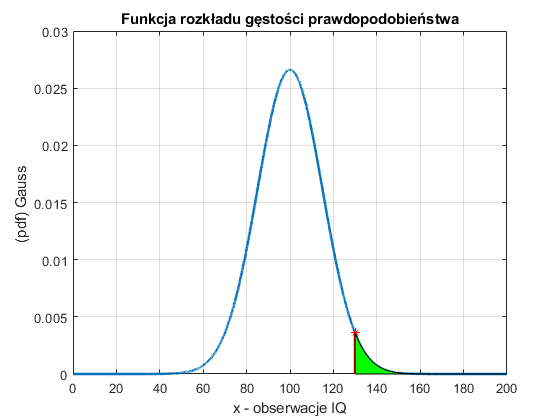

y = pdf(pd,t);
area(t,y,'FaceColor','g');

- oblicz prawdopodobieństwo $P\left(x>\mu +3\sigma \right)$ czyli przedział  obejmujący zakres IQ > 145 - czyli "prawy ogon rozkładu"?

xiq=mu+3*sigma

xiq = 145

p8=1-cdf('Normal',xiq,mu,sigma)

p8 = 0.0013

Wyrażone w procentach %

p8_proc=p8*100 %

p8_proc = 0.1350

Wykres

figure (3)
x=0:0.01:200

x =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


plot(x,pdf_normal,'LineWidth',2)
xlabel('x - obserwacje IQ')
ylabel('(pdf) Gauss ')
title('Funkcja rozkładu gęstości prawdopodobieństwa')
grid on
hold on
a = [mu+3*sigma mu+3*sigma]

a =    145   145


b = [0 pdf(pd,a(2))]

b = 	1.0e+-3 *

         0    0.2955


plot(a(2),pdf(pd,a(2)),'r*')
line(a,b,'Color','red','LineStyle','-','LineWidth',2)
t = mu+3*sigma:0.1:max(x)

t =   145.0000  145.1000  145.2000  145.3000  145.4000  145.5000  145.6000  145.7000  145.8000  145.9000  146.0000  146.1000  146.2000  146.3000  146.4000  146.5000  146.6000  146.7000  146.8000  146.9000  147.0000  147.1000  147.2000  147.3000  147.4000  147.5000  147.6000  147.7000  147.8000  147.9000  148.0000  148.1000  148.2000  148.3000  148.4000  148.5000  148.6000  148.7000  148.8000  148.9000  149.0000  149.1000  149.2000  149.3000  149.4000  149.5000  149.6000  149.7000  149.8000  149.9000


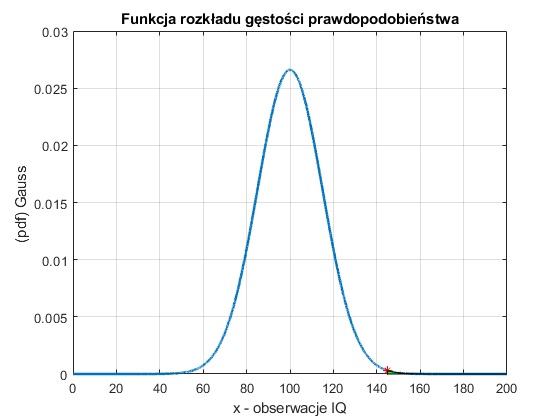

y = pdf(pd,t);
area(t,y,'FaceColor','g');

## **Rozkład normalny standaryzowany**

**Własność **

Jeżeli $X~N\left(\mu ,\sigma \right)$

to zmienna standaryzowana $Z=\frac{X-\mu }{\sigma }$ ma rozkład normalny standaryzowany Z~N(0,1)

**Przykład 1**

Dany jest rozkład N(100,15).

Oblicz $F\left(115\right)=P\left(X\le 115\right)$ z użyciem rozkładu normalnego standaryzowanego.

$P\left(X\le 115\right)$=$P\left(Z=\frac{X-100}{15}\le \frac{115-100}{15}=1\right)$=P$\left(Z\le 1\right)$=F(1)

Z użyciem funkcji **normcdf:**

p_z=normcdf(1)

p_z = 0.8413


figure (4)
mu=0

mu = 0

sigma=1

sigma = 1

z=-5:0.01:5

z =    -5.0000   -4.9900   -4.9800   -4.9700   -4.9600   -4.9500   -4.9400   -4.9300   -4.9200   -4.9100   -4.9000   -4.8900   -4.8800   -4.8700   -4.8600   -4.8500   -4.8400   -4.8300   -4.8200   -4.8100   -4.8000   -4.7900   -4.7800   -4.7700   -4.7600   -4.7500   -4.7400   -4.7300   -4.7200   -4.7100   -4.7000   -4.6900   -4.6800   -4.6700   -4.6600   -4.6500   -4.6400   -4.6300   -4.6200   -4.6100   -4.6000   -4.5900   -4.5800   -4.5700   -4.5600   -4.5500   -4.5400   -4.5300   -4.5200   -4.5100


pd=makedist('Normal','mu',mu,'sigma',sigma);
pdf_normal = pdf(pd,z);

plot(z,pdf_normal,'LineWidth',2)
xlabel('z - obserwacje IQ')
ylabel('(pdf) Gauss ')
title('Funkcja rozkładu gęstości prawdopodobieństwa')
grid on
hold on
a = [mu+sigma mu+sigma]

a =      1     1


b = [0 pdf(pd,a(2))]

b =          0    0.2420


plot(a(2),pdf(pd,a(2)),'r*')
line(a,b,'Color','red','LineStyle','-','LineWidth',2)
t = min(z):0.1:mu+sigma

t =    -5.0000   -4.9000   -4.8000   -4.7000   -4.6000   -4.5000   -4.4000   -4.3000   -4.2000   -4.1000   -4.0000   -3.9000   -3.8000   -3.7000   -3.6000   -3.5000   -3.4000   -3.3000   -3.2000   -3.1000   -3.0000   -2.9000   -2.8000   -2.7000   -2.6000   -2.5000   -2.4000   -2.3000   -2.2000   -2.1000   -2.0000   -1.9000   -1.8000   -1.7000   -1.6000   -1.5000   -1.4000   -1.3000   -1.2000   -1.1000   -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -0.1000


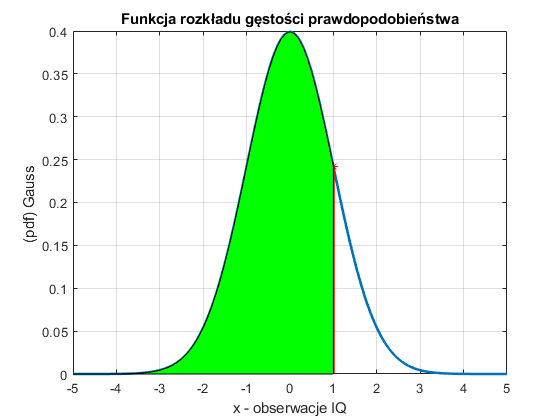

y = pdf(pd,t);
area(t,y,'FaceColor','g');

lub z użyciem funkcji **cdf**:

p_z2=cdf('Normal',1.00,0,1)

p_z2 = 0.8413

odpowiada to w rozkładzie niestandaryzowanym obliczeniu:

p_z3=cdf('Normal',115,100,15)

p_z3 = 0.8413

Przykład 2

Dany jest rozkład normalny (wzrostu w badanej populacji wyrażony w [cm]) o parametrach: N(175,4)

Oblicz $P\left(X\le 180\right)$=F(180)

$P\left(X\le 180\right)$=$P\left(z=\frac{X-175}{4}\le \frac{180-175}{4}=1,25\right)$=P$\left(Z\le 1,25\right)$=F(1,25)

zx=1.25

zx = 1.2500

p_z4=normcdf(zx)

p_z4 = 0.8944

wykres:

figure (5)
mu=0

mu = 0

sigma=1

sigma = 1

z=-5:0.01:5

z =    -5.0000   -4.9900   -4.9800   -4.9700   -4.9600   -4.9500   -4.9400   -4.9300   -4.9200   -4.9100   -4.9000   -4.8900   -4.8800   -4.8700   -4.8600   -4.8500   -4.8400   -4.8300   -4.8200   -4.8100   -4.8000   -4.7900   -4.7800   -4.7700   -4.7600   -4.7500   -4.7400   -4.7300   -4.7200   -4.7100   -4.7000   -4.6900   -4.6800   -4.6700   -4.6600   -4.6500   -4.6400   -4.6300   -4.6200   -4.6100   -4.6000   -4.5900   -4.5800   -4.5700   -4.5600   -4.5500   -4.5400   -4.5300   -4.5200   -4.5100


pd=makedist('Normal','mu',mu,'sigma',sigma);
pdf_normal = pdf(pd,z);

plot(z,pdf_normal,'LineWidth',2)
xlabel('z - obserwacje IQ')
ylabel('(pdf) Gauss ')
title('Funkcja rozkładu gęstości prawdopodobieństwa')
grid on
hold on
a = [zx zx]

a =     1.2500    1.2500


b = [0 pdf(pd,a(2))]

b =          0    0.1826


plot(a(2),pdf(pd,a(2)),'r*')
line(a,b,'Color','red','LineStyle','-','LineWidth',2)
t = min(z):0.1:zx

t =    -5.0000   -4.9000   -4.8000   -4.7000   -4.6000   -4.5000   -4.4000   -4.3000   -4.2000   -4.1000   -4.0000   -3.9000   -3.8000   -3.7000   -3.6000   -3.5000   -3.4000   -3.3000   -3.2000   -3.1000   -3.0000   -2.9000   -2.8000   -2.7000   -2.6000   -2.5000   -2.4000   -2.3000   -2.2000   -2.1000   -2.0000   -1.9000   -1.8000   -1.7000   -1.6000   -1.5000   -1.4000   -1.3000   -1.2000   -1.1000   -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -0.1000


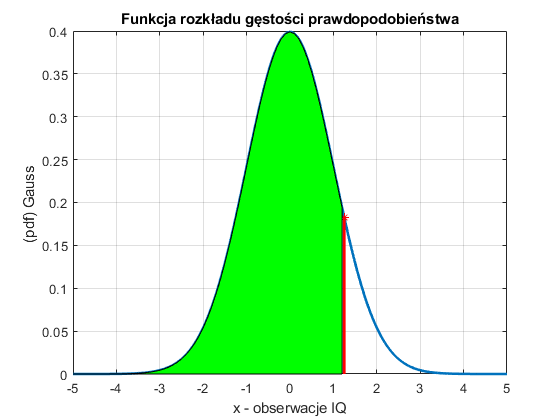

y = pdf(pd,t);
area(t,y,'FaceColor','g');

lub

p_z5=cdf('Normal',1.25,0,1)

p_z5 = 0.8944

odpowiada to w rozkładzie niestandaryzowanym:

p_z6=cdf('Normal',180,175,4)

p_z6 = 0.8944

Przykład 3

Wyznacz taki punkt x, dla kórego wartość dystrybuanty równa jest 0,5 (rozkład normalny niestandaryzowany)

mu=100

mu = 100

sigma=15

sigma = 15

pd=makedist('Normal','mu',mu,'sigma',sigma);
p=0.5

p = 0.5000

Funkcja** icdf - ***Inverse cumulative distribution function*

[Funkcja "icdf"](https://www.mathworks.com/help/releases/R2020a/stats/prob.normaldistribution.icdf.html)

x_prz3=icdf(pd,p)

x_prz3 = 100

Przykład 4

Wyznacz taki punkt z (rozkład normalny standaryzowany), dla kórego wartość dystrybuanty równa jest 0,2 czyli F(z)=0,2

mu=0

mu = 0

sigma=1

sigma = 1

pd=makedist('Normal','mu',mu,'sigma',sigma);
p=0.2

p = 0.2000

z_p4=icdf(pd,p)

z = -0.8416


figure (6)
z=-5:0.01:5

x =    -5.0000   -4.9900   -4.9800   -4.9700   -4.9600   -4.9500   -4.9400   -4.9300   -4.9200   -4.9100   -4.9000   -4.8900   -4.8800   -4.8700   -4.8600   -4.8500   -4.8400   -4.8300   -4.8200   -4.8100   -4.8000   -4.7900   -4.7800   -4.7700   -4.7600   -4.7500   -4.7400   -4.7300   -4.7200   -4.7100   -4.7000   -4.6900   -4.6800   -4.6700   -4.6600   -4.6500   -4.6400   -4.6300   -4.6200   -4.6100   -4.6000   -4.5900   -4.5800   -4.5700   -4.5600   -4.5500   -4.5400   -4.5300   -4.5200   -4.5100


pd=makedist('Normal','mu',mu,'sigma',sigma);
pdf_normal = pdf(pd,z);
plot(z,pdf_normal,'LineWidth',2)
xlabel('z - obserwacje IQ')
ylabel('(pdf) Gauss ')
title('Funkcja rozkładu gęstości prawdopodobieństwa')
grid on
hold on
a = [z_p4 z_p4]

a =    -0.8416   -0.8416


b = [0 pdf(pd,a(2))]

b =          0    0.2800


plot(a(2),pdf(pd,a(2)),'r*')
line(a,b,'Color','red','LineStyle','-','LineWidth',2)
t = -5:0.1:z_p4

t =    -5.0000   -4.9000   -4.8000   -4.7000   -4.6000   -4.5000   -4.4000   -4.3000   -4.2000   -4.1000   -4.0000   -3.9000   -3.8000   -3.7000   -3.6000   -3.5000   -3.4000   -3.3000   -3.2000   -3.1000   -3.0000   -2.9000   -2.8000   -2.7000   -2.6000   -2.5000   -2.4000   -2.3000   -2.2000   -2.1000   -2.0000   -1.9000   -1.8000   -1.7000   -1.6000   -1.5000   -1.4000   -1.3000   -1.2000   -1.1000   -1.0000   -0.9000


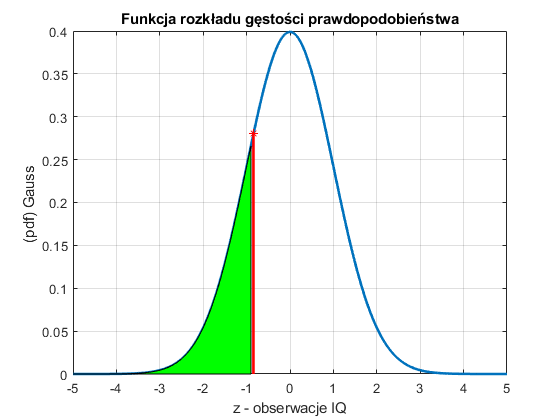

y = pdf(pd,t);
area(t,y,'FaceColor','g');

Przykład 5

Wyznacz taki punkt z, dla kórego wartość dystrybuanty równa jest 0,5 czyli F(z)=0,5.

mu=0

mu = 0

sigma=1

sigma = 1

pd=makedist('Normal','mu',mu,'sigma',sigma);
p=0.5

p = 0.5000

z_p5=icdf(pd,p)

z = 0


figure (7)
z=-5:0.01:5

x =    -5.0000   -4.9900   -4.9800   -4.9700   -4.9600   -4.9500   -4.9400   -4.9300   -4.9200   -4.9100   -4.9000   -4.8900   -4.8800   -4.8700   -4.8600   -4.8500   -4.8400   -4.8300   -4.8200   -4.8100   -4.8000   -4.7900   -4.7800   -4.7700   -4.7600   -4.7500   -4.7400   -4.7300   -4.7200   -4.7100   -4.7000   -4.6900   -4.6800   -4.6700   -4.6600   -4.6500   -4.6400   -4.6300   -4.6200   -4.6100   -4.6000   -4.5900   -4.5800   -4.5700   -4.5600   -4.5500   -4.5400   -4.5300   -4.5200   -4.5100


pd=makedist('Normal','mu',mu,'sigma',sigma);
pdf_normal = pdf(pd,z);
plot(x,pdf_normal,'LineWidth',2)
xlabel('z - obserwacje IQ')
ylabel('(pdf) Gauss ')
title('Funkcja rozkładu gęstości prawdopodobieństwa')
grid on
hold on
a = [z_p5 z_p5]

a =      0     0


b = [0 pdf(pd,a(2))]

b =          0    0.3989


plot(a(2),pdf(pd,a(2)),'r*')
line(a,b,'Color','red','LineStyle','-','LineWidth',2)
t = -5:0.1:z_p5

t =    -5.0000   -4.9000   -4.8000   -4.7000   -4.6000   -4.5000   -4.4000   -4.3000   -4.2000   -4.1000   -4.0000   -3.9000   -3.8000   -3.7000   -3.6000   -3.5000   -3.4000   -3.3000   -3.2000   -3.1000   -3.0000   -2.9000   -2.8000   -2.7000   -2.6000   -2.5000   -2.4000   -2.3000   -2.2000   -2.1000   -2.0000   -1.9000   -1.8000   -1.7000   -1.6000   -1.5000   -1.4000   -1.3000   -1.2000   -1.1000   -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -0.1000


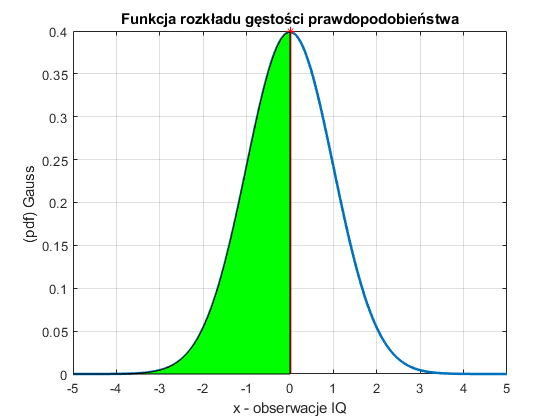

y = pdf(pd,t);
area(t,y,'FaceColor','g');

Przykład 6

Wyznacz taki punkt x - N(100,15), dla kórego wartość dystrybuanty równa jest 0,8 czyli F(z)=0,8 ?

mu=100

mu = 100

sigma=15

sigma = 15

pd=makedist('Normal','mu',mu,'sigma',sigma);
p=0.8

p = 0.8000

x_p6=icdf(pd,p)

x_p6 = 112.6243

wykres

figure (8)
x=0:01:200

x =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


mu=100

mu = 100

sigma=15

sigma = 15

pd=makedist('Normal','mu',mu,'sigma',sigma);
pdf_normal = pdf(pd,x);
plot(x,pdf_normal,'LineWidth',2)
xlabel('x - obserwacje IQ')
ylabel('(pdf) Gauss ')
title('Funkcja rozkładu gęstości prawdopodobieństwa')
grid on
hold on
a = [x_p6 x_p6]

a =   112.6243  112.6243


b = [0 pdf(pd,a(2))]

b =          0    0.0187


plot(a(2),pdf(pd,a(2)),'r*')
line(a,b,'Color','red','LineStyle','-','LineWidth',2)
t = 0:0.1:x_p6

t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


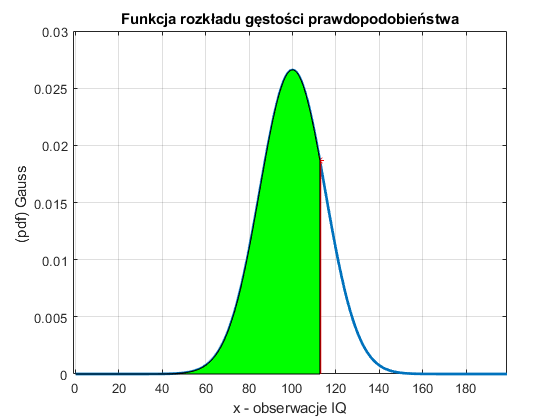

y = pdf(pd,t);
area(t,y,'FaceColor','g');